# Nullstellen eines Polynoms als Eigenwerte der Begleitmatrix

Sei ein Polynom in der monomialen Darstellung 

                    $p(x)=\sum_{j=0}^n c_{j}x^j$ mit $c_n=1$

gegeben. Die Koeffizienten $c_j$, $0\leq j \leq n-1$, werden gewählt:

fprintf('\nGrad des Polynoms: \n');


Grad des Polynoms: 


n=10

n = 10

c=zeros(n+1,1);
for i=1:n
%    c(i)=sin(i)^3;
%     c(i)=randn(1);   % andere Wahl der Koeffizienten im Polynom 
     c(i)=1/i;        % andere Wahl der Koeffizienten im Polynom 
end
c(n+1)=1;

Die zugehörige Begleitmatrix wird bestimmt und von der Matrix werden mithilfe der Matlab-Routine `eig` die Eigenwerte bestimmt:

A=Begleitmatrix(c); % Begleitmatrix wird bestimmt
result=eig(A);      % Eigenwerte werden über Matlab-Routine eig(.) berechnet

Die berechneten Annäherungen der Nullstellen werden geplottet:

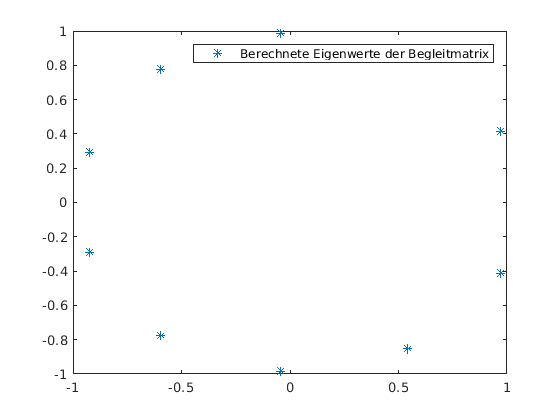

plot(real(result),imag(result),'*');
legend('Berechnete Eigenwerte der Begleitmatrix');

Als Maß für  die Genauigkeit wird der maximale Fehler $\mathrm{error}:=\max_{i=1\ldots,n}|p(\tilde x_i)|$ berechnet, wobei $\tilde x_i$, $1 \leq i \leq n$,  die berechneten Annäherungen der Eigenwerte der Begleitmatrix sind.

pWert=polyval(flip(c),result);  % Polynom wird ausgewertet
fprintf('\nFehlermaß: \n');


Fehlermaß: 


error=norm(pWert,Inf)

error = 1.3325e-14

# Aktivität:

Sie können den Polynomgrad $n$ variieren (z.B. $n \in \{4,10,15,20,40\}$) und ggf. eine andere Vorschrift für die Wahl der Koeffizienten $c_j$ nehmen. 

Es stellt sich heraus, dass mit dieser Methode alle Nullstellen mit hoher Genauigkeit berechnet werden.

*Bemerkung: *Diese Methode wird in der Matlab-Routine `roots` zur Bestimmung von Nullstellen von Polynomen verwendet.  

function A = Begleitmatrix(c)
    n=length(c)-1; % Polynomgrad
    A=zeros(n,n);
    for i=1:n-1
        A(i,i+1)=1;
    end
    A(n,:)= -c(1:n);
end